Author name: **Arjan Gupta**

Due date: March 20, 2023

Title of assignment in prompt: LE and Multi-link Manipulator

Class: RBE 501

Institution: Worcester Polytechnic Institute

# Dynamics Equations for Multi-Link Manipulators

## Introduction

In this assignment, we aim to derive the equations of motion for 2 different types of manipulators. The equations of the motion take on the following form.


$$M\left(q\right)\ddot{q} \;+\;C\left(q,\dot{q} \right)\dot{q} \;+\;G\left(q\right)\;=\;\tau$$


Where, *M *is the mass matrix, *C* is the matrix of Coriolis/Christoffel terms, and *G* is the matrix of gravitational forces. Also, $\ddot{q}$, $\dot{q}$, $q$ are the *n* dimensional vectors joint accelerations, joint velocities, and joint configurations. Here, *n* means the the number of joints we are considering.

Furthermore, there are two methods to solve the problem (although they are really the same method, just organized differently). The first is the Lagrange-Euler  (LE) method, which is noted in the assignment prompt title as the expected way to solve this problem. The second way involves methodically finding the Coriolis terms.

## Problem 1

Figure

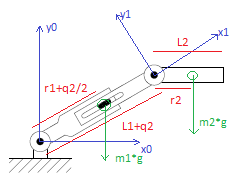

In this problem, we define $r_1$ as the distance between the world frame origin and the center of mass $m_1$ of the first link, $L_1 +q_2$, where $L_1$ is the fixed length and $q_2$ is the variable length due to the prismatic joint. Since the problem statement assumes that this link is has a mass with homogeneous density, we assume that the center of mass is always at half of the link length, so it is $r_1 +\frac{q_2 }{2}$ . The variable angle of the first joint is $q_1$. The second link has a constant length $L_2$, and a distance to center of mass $r_2$. The variable angle of the second joint is $q_2$.

### Solution A: E**xpected Way**

**Lagrange-Euler (LE) method**

clear; close all; clc;
syms r1 r2 q1(t) q2(t) q3(t) L1 L2 m1 m2 I1 I3 g tau1 f2 tau3

In this method, we take the following steps:

- Find the total kinetic energy of the system (*T)*

- Find the total potential energy of the system (U)

- Establish the Lagrangian as $L=T-U$

- Compute the derivatives for the Euler-Lagrange equation

Step 1: Find total kinetic energy

For the total kinetic energy, we consider the linear kinetic energy, $\frac{1}{2}{\textrm{mv}}^2$ and the rotational energy, $\frac{1}{2}I\omega^2$.

% Calculate linear velocity for link 1
% q2 = 0;
x1 = (r1 + q2/2)*cos(q1);
y1 = (r1 + q2/2)*sin(q1);
lin_v1 = diff(x1,t)^2 + diff(y1,t)^2;
% Linear and rotational KE for link 1
KE1_lin = (1/2)*m1*lin_v1^2;
KE1_rot = (1/2)*I1*(diff(q1,t))^2;
% Total KE for link 1
KE1 = KE1_lin + KE1_rot;

% Calculate linear velocity for link 2
x2 = (L1+q2)*cos(q1) + r2*cos(q1+q3);
y2 = (L1+q2)*sin(q1) + r2*sin(q1+q3);
lin_v2 = diff(x2,t)^2 + diff(y2,t)^2;
% Linear and rotational KE for link 2
KE2_lin = (1/2)*m2*lin_v2^2;
KE2_rot = (1/2)*I3*(diff(q1,t) + diff(q3,t))^2;
% Total KE for link 2
KE2 = KE2_lin + KE2_rot;

% Total KE for system
T = KE1 + KE2;
T = simplify(T);
display(T)

$$T(t) = \begin{array}{l} \frac{m_{2}\,{\left({\left(\sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)+r_{2}\,\cos\left(\sigma_{3}\right)\,\sigma_{1}+\cos\left(q_{1}\left(t\right)\right)\,\left(L_{1}+q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}+{\left(-\cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)+\sin\left(q_{1}\left(t\right)\right)\,\left(L_{1}+q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)+r_{2}\,\sin\left(\sigma_{3}\right)\,\sigma_{1}\right)}^{2}\right)}^{2}}{2}+\frac{m_{1}\,{\left(4\,{r_{1}}^{2}\,\sigma_{2}+4\,r_{1}\,q_{2}\left(t\right)\,\sigma_{2}+{q_{2}\left(t\right)}^{2}\,\sigma_{2}+{\left(\frac{\partial }{\partial t}q_{2}\left(t\right)\right)}^{2}\right)}^{2}}{32}+\frac{I_{1}\,\sigma_{2}}{2}+\frac{I_{3}\,{\sigma_{1}}^{2}}{2}\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial }{\partial t}q_{1}\left(t\right)+\frac{\partial }{\partial t}q_{3}\left(t\right)\\ \sigma_{2}={\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}\\ \sigma_{3}=q_{1}\left(t\right)+q_{3}\left(t\right) \end{array}$$

Step 2: Find total potential energy

The formula for potential energy is simply $\textrm{PE}=m\cdot g\cdot h$. We then take the derivatives (w.r.t. the joint variables) of the total PE to come up with the elements of the *G* matrix. The *G* matrix is a vector.

Accordingly to our figure, the center of masses of $m_1$ and $m_2$ are at heights $h_1 =\left(r_1 +\frac{q_2 }{2}\right)\sin \left(q_1 \right)$ and $h_2 =L_1 \;\sin \left(q_1 \right)+r_2 \;\sin \left(q_1 +q_3 \right)$, correspondingly.

PE1 = m1*g*(r1+q2/2)*sin(q1);
PE2 = m2*g*(L1*sin(q1)+r2*sin(q1+q3));

% Total PE for the system
U = PE1 + PE2;
U = simplify(U);
display(U)

$$U(t) = g\,m_{2}\,\left(L_{1}\,\sin\left(q_{1}\left(t\right)\right)+r_{2}\,\sin\left(q_{1}\left(t\right)+q_{3}\left(t\right)\right)\right)+g\,m_{1}\,\sin\left(q_{1}\left(t\right)\right)\,\left(r_{1}+\frac{q_{2}\left(t\right)}{2}\right)$$

Step 3: Write the Lagrangian

The Lagrangian is $L=T-U$.

L = T - U;
L = simplify(L);
display(L)

$$L(t) = \begin{array}{l} \frac{m_{2}\,{\left({\left(\sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)+r_{2}\,\cos\left(\sigma_{3}\right)\,\sigma_{1}+\cos\left(q_{1}\left(t\right)\right)\,\left(L_{1}+q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}+{\left(-\cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)+\sin\left(q_{1}\left(t\right)\right)\,\left(L_{1}+q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)+r_{2}\,\sin\left(\sigma_{3}\right)\,\sigma_{1}\right)}^{2}\right)}^{2}}{2}+\frac{m_{1}\,{\left(4\,{r_{1}}^{2}\,\sigma_{2}+4\,r_{1}\,q_{2}\left(t\right)\,\sigma_{2}+{q_{2}\left(t\right)}^{2}\,\sigma_{2}+{\left(\frac{\partial }{\partial t}q_{2}\left(t\right)\right)}^{2}\right)}^{2}}{32}+\frac{I_{1}\,\sigma_{2}}{2}+\frac{I_{3}\,{\sigma_{1}}^{2}}{2}-g\,m_{2}\,\left(L_{1}\,\sin\left(q_{1}\left(t\right)\right)+r_{2}\,\sin\left(\sigma_{3}\right)\right)-g\,m_{1}\,\sin\left(q_{1}\left(t\right)\right)\,\left(r_{1}+\frac{q_{2}\left(t\right)}{2}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial }{\partial t}q_{1}\left(t\right)+\frac{\partial }{\partial t}q_{3}\left(t\right)\\ \sigma_{2}={\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}\\ \sigma_{3}=q_{1}\left(t\right)+q_{3}\left(t\right) \end{array}$$

Step 4: Compute the derivatives for the Euler-Lagrange equation

The Euler-Lagrange equation as a dynamics equation is $\frac{\mathrm{d}}{\mathrm{d}t}\left(\frac{\partial }{\partial \dot{q_k } }L\right)-\left(\frac{\partial }{\partial q_k }L\right)=\tau_k$, where *k *denotes the joint number. In this problem, we are considering 3 joints, so there will be 3 equations of motion.

% Dynamics equation for q1
disp("LE Dynamics equations for q1");

LE Dynamics equations for q1


disp(getELDiffEOM(L,q1,t,tau1));


% Dynamics equation for q2
disp("LE Dynamics equations for q2");

LE Dynamics equations for q2


disp(getELDiffEOM(L,q2,t,f2));


% Dynamics equations for q3
disp("LE Dynamics equations for q3");

LE Dynamics equations for q3


disp(getELDiffEOM(L,q3,t,tau3));

### Solution B: Extra Method

**Jacobian & Coriolis method**

clear; close all; clc;
syms r1 r2 q1(t) q2(t) q3(t) L1 L2 m1 m2 I1 I3 g tau1 tau3

In this method, we take the following steps:

- Find linear Jacobians ($J_v$) for the center of mass of each link as an individual system

- Compute the kinetic energies of each link as an individual system, sum them to get *M* matrix 

- Generate the Coriolis and Christoffel terms for the *C* matrix

- Find the potential energy of each link as an individual system, sum them to get G matrix

- Combine the findings to produce the equations of motion (dynamic equations)

Step 1: Find linear Jacobians

% First link linear Jacobian
z0 = [0;0;1];
zeros_vec = zeros(3,1);
on1 = [(r1 + q2/2)*cos(q1); (r1+ q2/2)*sin(q1); 0];
o0 = zeros_vec;
Jv1 = [cross(z0, (on1-o0)), zeros_vec];

% Second link linear Jacobian
z1 = z0;
o1 = [L1*cos(q1); L1*sin(q1); 0];
on2 = [(L1+q2)*cos(q1) + r2*cos(q1+q3); (L1 + q2)*sin(q1) + r2*sin(q1+q3); 0];
Jv2 = [cross(z0, (on2-o0)), cross(z1, (on2-o1))];

Step 2: Find kinetic energies

The kinetic energy of each link can be found using the formula $\frac{1}{2}{\dot{q} }^T \left\lbrace m{J_v }^T J_v +I\right\rbrace \dot{q}$, where *I* is the matrix for the moment of intertia. However, since we want to leave things in the matrix form, we only consider the $\left\lbrace m{J_v }^T J_v +I\right\rbrace$ portion. Our intertia matrices in this case are $\left\lbrack \begin{array}{cc}
I_1  & 0\\
0 & 0
\end{array}\right\rbrack$ and $\left\lbrack \begin{array}{cc}
I_3  & I_3 \\
I_3  & I_3 
\end{array}\right\rbrack$ corresponding to joints $q_1$ and $q_3$.

% First link KE
I1_mat = [I1 0; 0 0];
KE1_mat = m1*(Jv1.'*Jv1) + I1_mat;

% Second link KE
I2_mat = [I3 I3; I3 I3];
KE2_mat = m2*(Jv2.'*Jv2) + I2_mat;

% Our mass matrix is our total KE
M = KE1_mat + KE2_mat;
M = simplify(M);
display(M)

$$M(t) = \begin{array}{l} \left(\begin{array}{cc} I_{1}+I_{3}+\frac{m_{1}\,{q_{2}\left(t\right)}^{2}}{4}+\sigma_{2}+{L_{1}}^{2}\,m_{2}+m_{1}\,{r_{1}}^{2}+m_{2}\,{r_{2}}^{2}+m_{1}\,r_{1}\,q_{2}\left(t\right)+2\,L_{1}\,m_{2}\,q_{2}\left(t\right)+2\,m_{2}\,r_{2}\,\cos\left(q_{3}\left(t\right)\right)\,q_{2}\left(t\right)+2\,L_{1}\,m_{2}\,r_{2}\,\cos\left(q_{3}\left(t\right)\right) & \sigma_{1}\\ \sigma_{1} & m_{2}\,{r_{2}}^{2}+\sigma_{3}+\sigma_{2}+I_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=m_{2}\,{r_{2}}^{2}+\sigma_{3}+L_{1}\,m_{2}\,\cos\left(q_{3}\left(t\right)\right)\,r_{2}+\sigma_{2}+L_{1}\,m_{2}\,q_{2}\left(t\right)+I_{3}\\ \sigma_{2}=m_{2}\,{q_{2}\left(t\right)}^{2}\\ \sigma_{3}=2\,m_{2}\,\cos\left(q_{3}\left(t\right)\right)\,r_{2}\,q_{2}\left(t\right) \end{array}$$

Step 3: Compute the *C* matrix

We use supporting functions to calculate the elements of the C matrix of our equations of motion.

q_vec = [q1, q3].';
q_dot_vec = [diff(q1,t), diff(q3,t)].';
C = computeCMatrix(M(t), 2, q_vec(t), q_dot_vec(t));
C = simplify(C);
display(C)

$$C = \begin{array}{l} \left(\begin{array}{cc} -m_{2}\,r_{2}\,\sin\left(q_{3}\left(t\right)\right)\,\left(L_{1}+q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{3}\left(t\right) & -m_{2}\,r_{2}\,\sin\left(q_{3}\left(t\right)\right)\,\left(L_{1}+2\,q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{3}\left(t\right)-\sigma_{1}\\ \sigma_{1} & -m_{2}\,r_{2}\,\sin\left(q_{3}\left(t\right)\right)\,q_{2}\left(t\right)\,\frac{\partial }{\partial t}q_{3}\left(t\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=m_{2}\,r_{2}\,\sin\left(q_{3}\left(t\right)\right)\,\left(L_{1}+q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right) \end{array}$$

Step 4: Compute the *G* matrix

The formula for potential energy is simply $\textrm{PE}=m\cdot g\cdot h$. We then take the derivatives (w.r.t. the joint variables) of the total PE to come up with the elements of the *G* matrix. The *G* matrix is a vector.

Accordingly to our figure, the center of masses of $m_1$ and $m_2$ are at heights $h_1 =\left(r_1 +\frac{q_2 }{2}\right)\sin \left(q_1 \right)$ and $h_2 =L_1 \;\sin \left(q_1 \right)+r_2 \;\sin \left(q_1 +q_3 \right)$, correspondingly.

PE1 = m1*g*(r1+q2/2)*sin(q1);
PE2 = m2*g*(L1*sin(q1)+r2*sin(q1+q3));
total_PE = PE1 + PE2;
dPE1 = diff(total_PE,q1);
dPE2 = diff(total_PE,q3);
G = [dPE1, dPE2].';
G = simplify(G);
display(G)

$$G(t) = \left(\begin{array}{c} g\,m_{2}\,\left(r_{2}\,\cos\left(q_{1}\left(t\right)+q_{3}\left(t\right)\right)+L_{1}\,\cos\left(q_{1}\left(t\right)\right)\right)+g\,m_{1}\,\cos\left(q_{1}\left(t\right)\right)\,\left(r_{1}+\frac{q_{2}\left(t\right)}{2}\right)\\ g\,m_{2}\,r_{2}\,\cos\left(q_{1}\left(t\right)+q_{3}\left(t\right)\right) \end{array}\right)$$

Step 5: Produce the equations of motion (dynamic equations)

We can produce the equations in the multiplied form,

q_dot_dot_vec = diff(q_dot_vec,t);
tau_vec = [tau1, tau3].';
EOM_LHS = M*q_dot_dot_vec + C*q_dot_vec + G;
EOM = EOM_LHS == tau_vec;
EOM = simplify(EOM);
disp("Dynamics equations, multiplied out")

Dynamics equations, multiplied out


display(EOM)

And we can also produce the equations in the non-multiplied form,

disp("Dynamics equations in matrix form")

Dynamics equations in matrix form


displayFormula("M*q_dot_dot_vec + C*q_dot_vec + G == tau_vec")


EOM_solB = EOM_LHS(t);
% EOM_solB(1)
isequaln(dyn_q1_LHS,EOM_solB(1))

ans = logical
   0


## Supporting Functions

### Coriolis Computation

The following function calculates the C matrix for our equations of motion. The details of how to do this is given in our textbook, *Robot Modeling and Control*.

function C = computeCMatrix(M, n, q, q_dot)
    C = sym(zeros(n));
    for r = 1:n
        for c = 1:n
            for qi = 1:n
                C(r,c) = C(r,c) + q_dot(qi)*getChristoffel(M,q,qi,c,r);
            end
        end
    end
end

The following function calculates the Christoffel Symbols for the C matrix of our equations of motion.

function term = getChristoffel(M,q,i,j,k)
    term = (1/2)*(diff(M(k,j),q(i)) + diff(M(k,i),q(j)) - diff(M(i,j),q(k)));
end

The following function avoids code reptition by calculating the Euler Lagrangian with respect to a particular joint variable.

function dyn_eq = getELDiffEOM(L,q,t,tau)
    dL_q = diff(L,q);
    dL_qdot = diff(L,diff(q,t));
    dt = diff(dL_qdot,t);
    dyn_q_LHS = dt - dL_q;
    dyn_q_LHS = simplify(dyn_q_LHS);
    dyn_eq = dyn_q_LHS == tau;
end